data = readtable("Interpolated_perpendicular_distance.csv")

data = 713×13 table
     x     Left_1    Right_1    Left_2    Right_2    Left_3    Right_3    Left_4    Right_4    Left_5    Right_5    Left_avg    Right_avg
    ___    ______    _______    ______    _______    ______    _______    ______    _______    ______    _______    ________    _________

    0.1      5.1       5.25     4.6809    4.7234     4.6596    4.8085     32.762    73.524     4.8511    4.8511      10.411      18.631  
    0.2     10.2       10.5     9.3617    9.4468     9.3191     9.617     65.524    147.05     9.7021    9.7021      20.821

data = [data.Left_avg, data.Right_avg, data.x];

data = data(20:end-10,:);
y = data(:,3);
xl = data(:,1);
xr = data(:,2);

x = (xl+xr)/2;

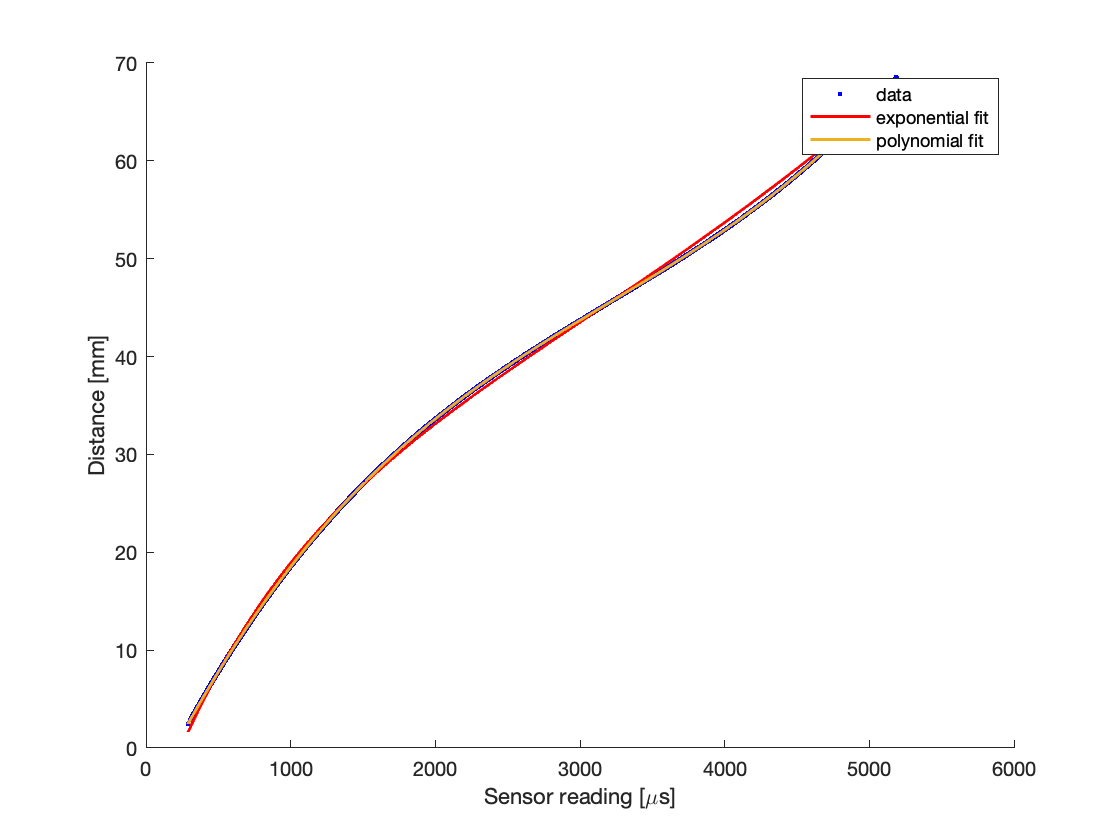

[p,S] = polyfit(x,y,3);
[y1,delta] = polyval(p,x,S);

[f,gof] = fit(x,y,'exp2');
figure
hold on
hl= plot(f, x, y);
set(hl, 'LineWidth', 1.5);
plot(x,y1,'LineWidth', 1.5);

legend('data','exponential fit','polynomial fit')
xlabel('Sensor reading [\mus]')
ylabel('Distance [mm]')

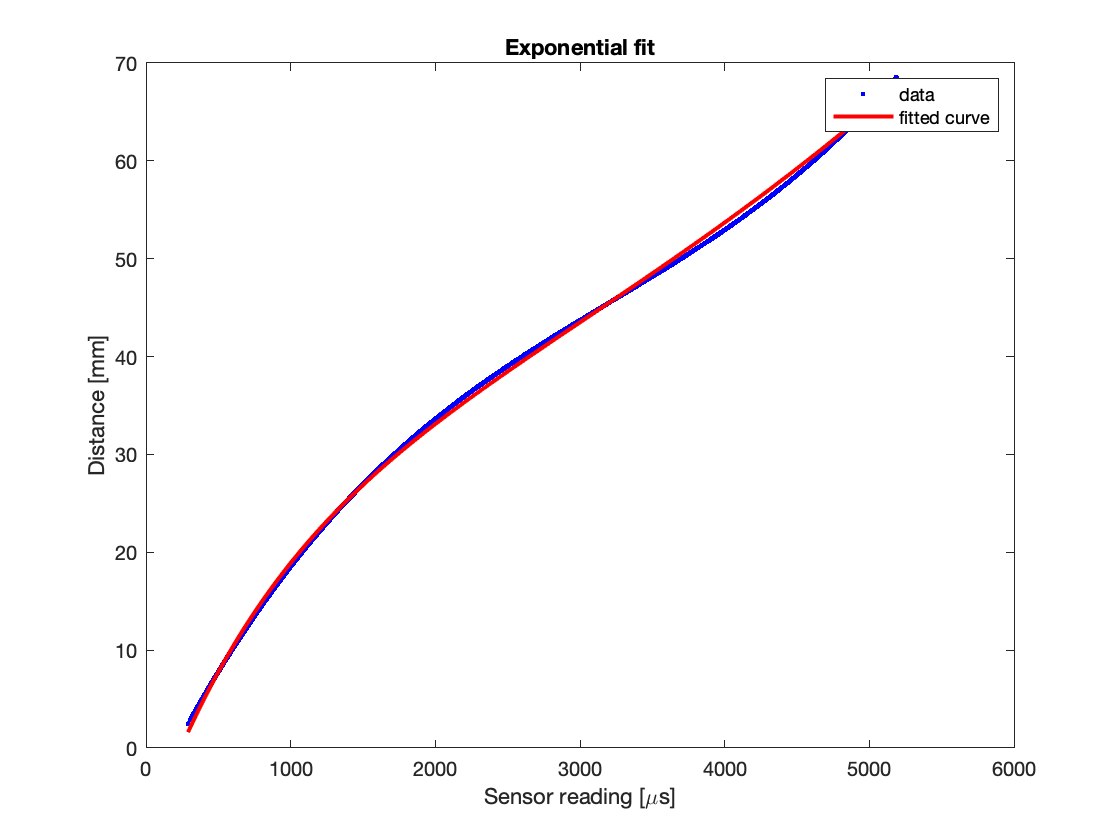

[f_exp,gof_exp] = fit(x,y,'exp2');
figure
h_exp= plot(f_exp, x, y);
set(h_exp, 'LineWidth', 2);
xlabel('Sensor reading [\mus]')
ylabel('Distance [mm]')
title('Exponential fit')

[f_pol,gof_pol] = fit(x,y,'poly4');

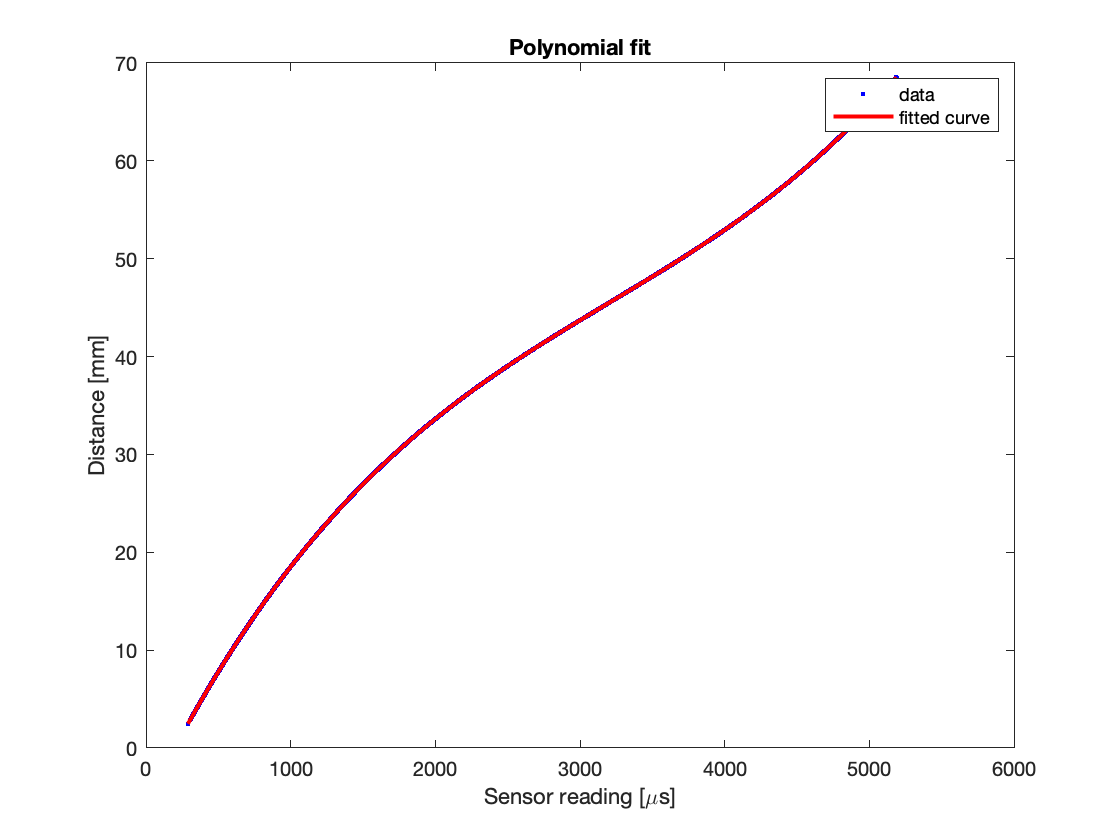

figure
h_pol= plot(f_pol, x, y);
set(h_pol, 'LineWidth', 2);
xlabel('Sensor reading [\mus]')
ylabel('Distance [mm]')
title('Polynomial fit')